clc;
clear all;
close all;

%Zero paading the image and writing to a file
img = [1 2 3 4 ;
    5 6 7 8 ;
    9 10 11 12;
    13 14 15 16];          % 64x64 (gray or RGB)
padded = padarray(img, [1 1], 0, 'both');  % add 1-pixel black border all sides

imshow(padded, []);
title(sprintf('Size after padding: %dx%d', size(padded,1), size(padded,2)));

imwrite(uint8(padded), 'C:\Users\aksha\OneDrive\Desktop\Project\FPGA IO Scripts\padded_image.png');% see the numeric matrix
padded

padded =      0     0     0     0     0     0
     0     1     2     3     4     0
     0     5     6     7     8     0
     0     9    10    11    12     0
     0    13    14    15    16     0
     0     0     0     0     0     0


% ==== Read already padded image ====
B = imread("C:\Users\aksha\OneDrive\Desktop\Project\FPGA IO Scripts\padded_image.png");
if size(B,3) == 3
    B = rgb2gray(B);     % ensure grayscale
end
B = double(B);

% Kernel (Sobel X)
kernel = [1 2;
    3 4];
 
% Dimensions
s = size(B)

s =      6     6


k = size(kernel)

k =      2     2


rows = s(1) - k(1) + 1   % valid convolution output rows

rows = 5

cols = s(2) - k(2) + 1   % valid convolution output cols

cols = 5

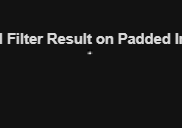


% Preallocate new_arr (im2col)
new_arr = zeros(k(1)*k(2), rows*cols);

% Fill new_arr row-major (patches flattened row by row)
count = 1;
for i = 1:rows
    for j = 1:cols
        arr = B(i:i+k(1)-1, j:j+k(2)-1);
        new_arr(:, count) = reshape(arr', [], 1);   % row-major flatten
        count = count + 1;
    end
end

% Flatten kernel & GEMM convolution
new_kernel = kernel(:)';           % 1 x (k1*k2)
conv_out = new_kernel * new_arr;   % (1x9 * 9xN) = 1xN
result = reshape(conv_out, [cols, rows])';

% Display result
figure;
imshow(mat2gray(result));
title('Sobel Filter Result on Padded Image');

imwrite(result, 'C:\Users\aksha\OneDrive\Desktop\Project\FPGA IO Scripts\filtered_image.png');
B

B =      0     0     0     0     0     0
     0     1     2     3     4     0
     0     5     6     7     8     0
     0     9    10    11    12     0
     0    13    14    15    16     0
     0     0     0     0     0     0


openvar new_arr
new_kernel

new_kernel =      1     3     2     4


disp(conv_out)

     4    10    16    22     8    23    41    51    61    20    51    81    91   101    32    79   121   131   141    44    39    55    59    63    16



result

result =      4    10    16    22     8
    23    41    51    61    20
    51    81    91   101    32
    79   121   131   141    44
    39    55    59    63    16
